cd 'E:\OneDrive\学习\大四下spring 2021\Advance Control Lab\Advance-Control-Lab\Preparatory Work 4'
clear
clc


s=tf('s'); Py=(100)/(s*(s+100)); Ptheta=-180/pi*(50*s^2)/(s^2+0.49*s+50);
C=(40*s+179)/s;
TF=feedback(C*Py,1)*Ptheta

TF =
 
                 -1.146e07 s^3 - 5.128e07 s^2
  ----------------------------------------------------------
  s^5 + 100.5 s^4 + 4099 s^3 + 24860 s^2 + 208771 s + 895000
 
Continuous-time transfer function.



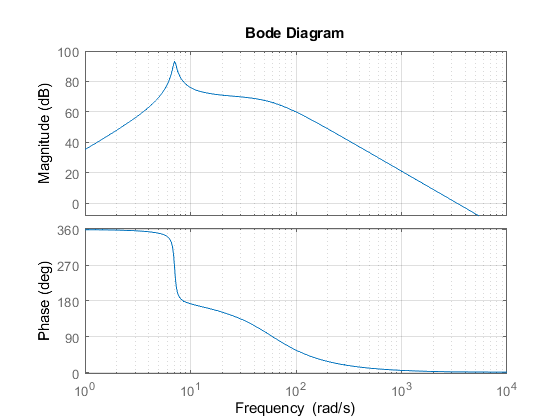

bode(TF); grid on;

[MAG,PHASE,W]=bode(TF);
Max_index=find(MAG==max(MAG));
Mag_max=mag2db(MAG(Max_index))

Mag_max = 93.0439

W_max=W(Max_index)

W_max = 7.0626

Ctheta=pidstd(-0.3,2);
% Ctheta= -0.3*(s+0.5)/s;
P2=feedback(TF,Ctheta)

P2 =
 
                       -1.146e07 s^4 - 5.128e07 s^3
  -----------------------------------------------------------------------
  s^6 + 100.5 s^5 + 3.442e06 s^4 + 1.713e07 s^3 + 7.901e06 s^2 + 895000 s
 
Continuous-time transfer function.



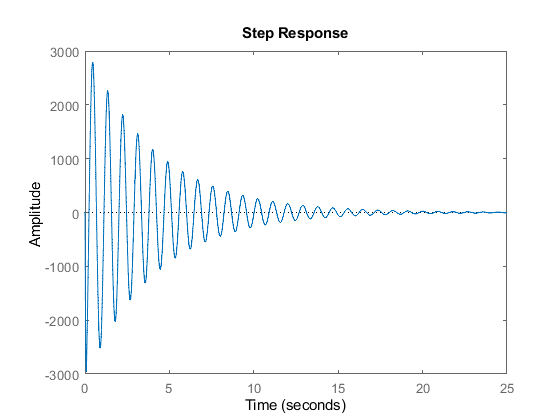



step(TF)

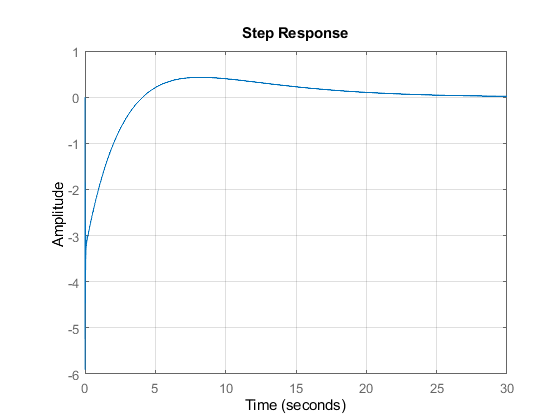


step(P2); grid on

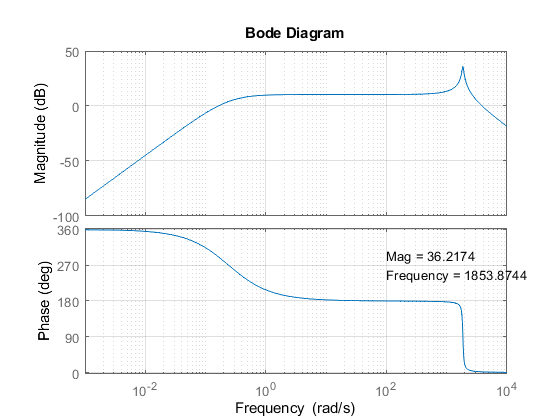

bode(P2); grid on; 
[P2_peak, P2_F]=getPeakGain(P2);P2_peak=mag2db(P2_peak);
str="Mag = " + num2str(P2_peak) + "\n" + "Frequency = " + num2str(P2_F);
str=compose(str); txt=splitlines(str);
text(100,270,txt)

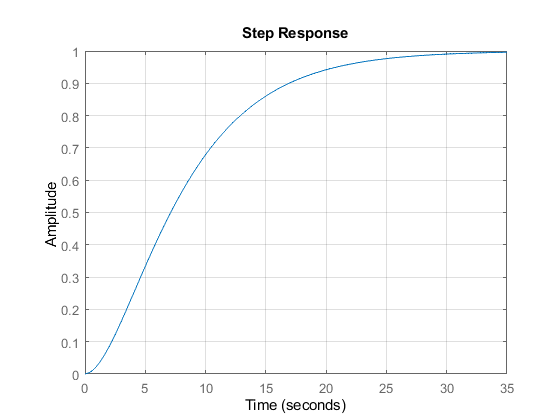


P2ry=P2/Ptheta;
step(P2ry); grid on